## E3

#### Filtrat lineal

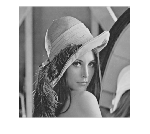

% filtres de suavitzat
I = imread('lena_gray_512.tif');
h = [1 1 1; 1 9 1; 1 1 1];
h = h/sum(sum(h)); % normalitzar la finestra de convolució

J = imfilter(I,h);
imshow(J);

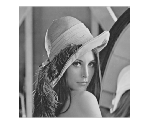

% gaussiana
h = fspecial("gaussian",5,0.8);
J = imfilter(I,h);
imshow(J);

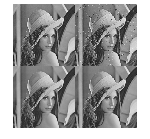

% filtre no lineal
IN = imnoise(I,'salt & pepper',0.02);
h = fspecial("gaussian",5,0.8);
M = medfilt2(IN,[3 3]);
G = imfilter(M,h);
montage({I,IN,G,M})

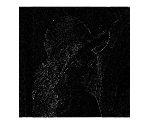

% filtre passa alts
I = imread('lena_gray_512.tif');
h = fspecial("gaussian",5,0.8);
J = imfilter(I,h);
D = abs(double(I)-double(J));
imshow(D,[])

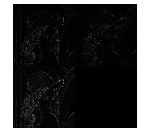

% derivada Gx Gy
hx = [1 -1; 1 -1];
hy = hx';
% la derivada són 2 filtres, un per la x i l'altre per la y
Gx = abs(imfilter(double(I),hx));
Gx = Gx/max(max(Gx));
Gy = abs(imfilter(double(I),hy));
Gy = Gy/max(max(Gy));
montage({Gx,Gy,Gx+Gy})

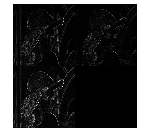

% derivada Gx Gy per sobel
hx = [1 0 -1; 2 0 -2; 1 0 -1];
hy = hx';

Gx = abs(imfilter(double(I),hx));
Gx = Gx/max(max(Gx));
Gy = abs(imfilter(double(I),hy));
Gy = Gy/max(max(Gy));
montage({Gx,Gy,Gx+Gy})

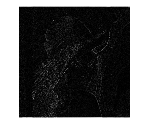

% Laplacia (segona derivada)
hL = [0 2 0; 2 -8 2; 0 2 0];
L = abs(imfilter(double(I),hL));
imshow(L,[])

% Laplacian of gaussian
% N = 30;
% hG = fspecial("gaussian",N,N/5);
% [X Y] = meshgrid(1:N,1:N);
% surf(X,Y,hG);
% 
% hLG = [0 1 0; 1 -4 1; 0 1 0];
% 
% dLG = imfilter(hG,hx,'replicate');
% 
% surf(X,Y,hLG);
% J = imfilter(double(I),hLG);
% 
% imshow(D,[])

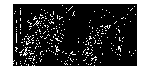

C = edge(I,"canny");
Z = edge(I,"zerocross",0.005);

montage({C,Z});

% extracció de contorn d'imatges en color

% es podria fer semblant als algorismes anteriors però per cada capa
% r, g i b, i fer una suma del resultat.